# The Two-Point Correlation Function in Non-stationary States

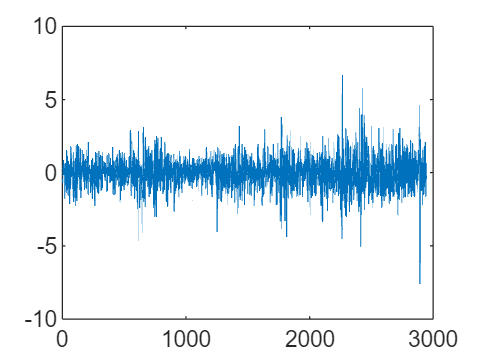

clear
load('index_2010_2024.mat');
P = HSI.price(749:end); % HSI.price(749:end) (HSI 2013-2024)
R = diff(log(P));
r = zscore(R);

% For convenience, standardize the input time series to column vector format.
if size(r,1) < size(r,2)
    r = r'; 
end
B = r; 

% A may represent either an internal driving force, such as dynamic fluctuations in various systems, 
% or an external one, such as external information in complex financial systems.
A = abs(r);

figure()
plot(B)

## Parameter setting

% This case examines the volatility-return correlation, 
% specifically the influence of intrinsic drivers on dynamic variables. 
% The following parameter settings are provided, which can be adjusted based on specific requirements.
T_para = [5,1,44,45,5,400]; % Parameters for time window traversal
tc = 100; % Length of two-point correlation function
tg = 10; % Length of multi-point correlation function
Q = 1; % Intrinsic drivers

## Initial correlation computation without considering non-stationary effects

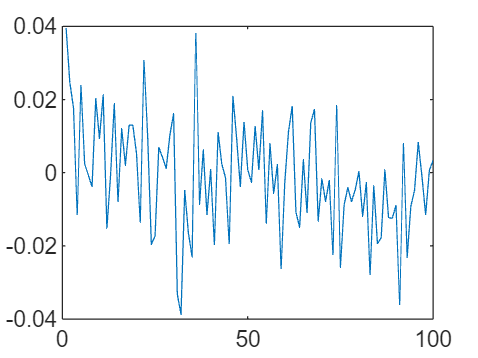

C_og = correlationTP_func(A,B,tc,0); % Parameter 0 means the magnitude of the driving force is taken into account.

figure()
plot(C_og)

## Optimal time window selection for two-point correlation

[AP0_tp,Am_tp,num_tp,T_opt_tp,Tb_opt_tp] = window_selection_TP_func(A,B,Q,T_para,tc);

[Am_tp,num_tp,T_opt_tp,Tb_opt_tp]

ans =      0.027249          219           24          150


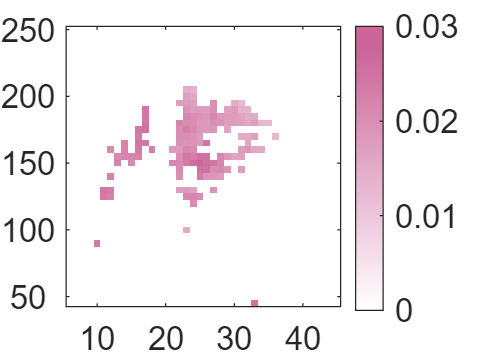

for Tb = 45:5:400
    AP0_plot(:,(Tb-40)/5) = AP0_tp(5:end,Tb);
    FAP0 = (AP0_plot)';
end



target_color = [0.8, 0.4, 0.6]; 
n_colors = 256; 
custom_colormap = [linspace(1, target_color(1), n_colors);
                   linspace(1, target_color(2), n_colors); 
                   linspace(1, target_color(3), n_colors)]';  
fontsize = 13;
figure()
imagesc(FAP0(1:42,:)); 
set(gca,'xtick',5:10:44,'xticklabel',10:10:40);
set(gca,'ytick',2:10:42,'yticklabel',50:50:250);
set(gca,'YDir','normal'); 
colormap(custom_colormap);
c = colorbar;
c.FontSize = fontsize;
c.Limits = [0, 0.03];
c.Ticks = [0:0.01:0.03]; 
% xlabel('$T$','Interpreter','latex')
% ylabel('$T_b$','Interpreter','latex','Rotation',0)
set(gca, fontsize=fontsize)

## The two-point correlation under the optimal time window

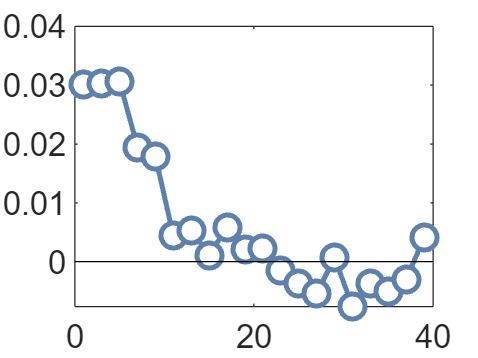

A_tp = removeBG_func(B,T_opt_tp,Tb_opt_tp,Q);
C_tp = correlationTP_func(A_tp,B,tc,1); % Parameter 1 means only the sign of the driving force is considered.

C_tp_smooth = smooth(C_tp,3);
x = 1 : length(C_tp_smooth);
x_plot = 1: 2 :length(C_tp_smooth);
figure()
% plot(C_og)
% hold on
plot(x(x_plot), C_tp_smooth(x_plot),'-o','color','#5E81AC','LineWidth',2,'MarkerSize',10,'MarkerFaceColor','auto')

% plot(smooth(C_tp,3),'k','LineWidth',2)
hold on
line([0,60],[0,0],'color','k')
xlim([0,40])
% xlabel('$t$','Interpreter','latex')
% ylabel('$\tilde{C}(t)$','Interpreter','latex','Rotation',0)
set(gca, fontsize=fontsize)

## [Function] Compute a new time series after removing background fluctuations

% [Input] S, T, Tb, Q
% S [N*1 column vector]: Original time series (e.g., return time series, sentiment index series)
% T [numeric]: Time window
% Tb [numeric]: Time window (Within this time window Tb, the dynamic system is in a quasi-steady state)
% Q [0/1 value]: Intrinsic drivers
%    Q = 1: for discussing intrinsic forces driving the dynamic system, such as the volatility.
%    Q = 0: for discussing external information driving the dynamic system, such as the sentiment index.

% [Output] Srbg
% Srbg [N*1 column vector]: The new time series after removing background fluctuations


function Srbg = removeBG_func(S,T,Tb,Q)

switch Q
    case 0 % External information drivers
        for t = Tb:length(S)
            STb(t,1) = mean( S(t-Tb+1:t) ); % data from the first Tb time points are invalid
        end
        for t = T:length(S)
            ST(t,1) = mean( S(t-T+1:t) );  % data from the first T time points are invalid
        end

    case 1 % Intrinsic drivers
        for t = Tb:length(S)
            STb(t,1) = std( S(t-Tb+1:t) );  % data from the first Tb time points are invalid
        end
        for t = T:length(S)
            ST(t,1) = std( S(t-T+1:t) );  % data from the first T time points are invalid
        end
end

Srbg = ST - STb;
end

## [Function] Compute the two-point correlation function

% [Input] A, B, tc, SG
% A [N*1 column vector]: Time series A (e.g., volatility series)
% B [N*1 column vector]: Time series B (e.g., return series)
% tc [numeric]: Length of two-point correlation function
% SG [0/1 value]: Different details in the calculation of the correlation function. 
%     SG = 1 means only the sign of the driving force is considered, 
%     SG = 0 means the magnitude of the driving force is taken into account.

% [Output] C
% C [tc*1 column vector]: The correlation function C

function C = correlationTP_func(A,B,tc,SG)

switch SG
    case 0
        for t = 1:tc
            C(t,1) = mean( A( 1:end-t ).*B( 1+t:end ) ) - mean( A( 1:end-t ) )* mean( B( 1+t:end ) );
        end

    case 1
        SA = sign(A);
        if size(SA,1) < size(SA,2)
            SA = SA';
        end
        for t = 1:tc
            C(t,1) = mean( SA( 1:end-t ).*B( 1+t:end ) ) - mean( SA( 1:end-t ) )* mean( B( 1+t:end ) );
        end
end

end

## [Function] Filter effective time window pairs and optimal time window pairs using the two-point correlation function

% [Input] A, B, Q, T_para, tc
% B [N*1 column vector]: Dynamic system variable (e.g., returns)
% A [N*1 column vector]: Dynamical quantity driving the system (e.g., volatility, sentiment index)
% Q [0/1 value]: Intrinsic drivers
%    Q = 1: A is the intrinsic driving force of the dynamic system, such as the volatility.
%    Q = 0: A is the external information driving force of the dynamic system, such as the sentiment index.
% T_para = [T_start, T_step, T_stop, Tb_start, Tb_step, Tb_stop]: Parameters for time window traversal
% tc [numeric]: Length of two-point correlation function

% [Output] AP0, Am, num, T_opt, Tb_opt
% AP0 [T_stop*Tb_stop matrix]: Effective correlation strength
% Am [numeric]: Correlation strength under the optimal time windows
% num [numeric]: Number of the effective time window pairs
% T_opt [numeric], Tb_opt [numeric]: Optimal time window pairs

% [Special Note] 
% In this function, t2 and SG are adjustable parameters. 
% They can be modified according to the specific situation.
% In this case, t2 = 25 and SG = 1.

function [AP0,Am,num,T_opt,Tb_opt] = window_selection_TP_func(A,B,Q,T_para,tc)

t2 = 25; 
SG = 1;

T_start = T_para(1);
T_step = T_para(2);
T_stop = T_para(3);
Tb_start = T_para(4);
Tb_step = T_para(5);
Tb_stop =T_para(6);

for T = T_start:T_step:T_stop
    for Tb = Tb_start:Tb_step:Tb_stop
        % step 1: Calculate the correlation function
        A_ = [];
        if Q == 1
            A_ = removeBG_func(B,T,Tb,Q);
        else
            A_ = removeBG_func(A,T,Tb,Q);
        end
        C = correlationTP_func( A_(T_stop+Tb_stop+1:end),B(T_stop+Tb_stop+1:end),tc,SG );  
        % For consistency, it is recommended to remove the first T_stop+Tb_stop data points from all data, 
        % so that when selecting the optimal window, the length of all valid data is consistent.
        SC = smooth( C,3 ); % Parameter 3 represents smoothing with a 3-point window

        % step 2: Find the first sign-changing point t1
        t1 = 1;
        while sign(SC(t1)) == sign(SC(1))
            t1 = t1+1;
            if t1 >= length(SC)
                break
            end
        end

        % step 3: Divide the correlation function into two parts based on t1
        P1 = SC( 1:t1-1 );
        AP1 = mean(abs( P1 ));
        P2 = SC( t1:min(length(SC),t1+t2-1));
        AP2 = mean(abs( P2 ));

        % step 4: Find t0 based on AP2 and compute AP0
        t0 = 1;
        while SC(t0)*sign(SC(1)) > AP2
            t0 = t0+1;
        end
        if t0 > 10 && all(abs(P2) < AP1)
            AP0(T,Tb) = mean( SC(1:t0) );
        else
            AP0(T,Tb) = 0;
        end
    end
end

% step 5: Count the number of valid time windows
num = length( find(AP0~=0) );
aAP0 = abs(AP0);
[T_opt,Tb_opt] = find( aAP0==max(max(aAP0)) );
T_opt = T_opt(1);
Tb_opt = Tb_opt(1);
Am = AP0(T_opt,Tb_opt);
end